# Task 3 - Number plate recognition

## Pre-processing

figure;

### Read images and turn them to grayscale

img_path = "images/final/task_3/";

image1 = imread(img_path + "example_number_plate.png");
subplot(2, 2, 1); imshow(image1); title("Original Image");

img1gray = rgb2gray(image1);
subplot(2, 2, 2); imshow(img1gray); title("1. Grayscale");

### Noise removal

% Here I guess we could use imbilatfilt to filter it 
% bilaterally like in the documentation.
img1med = medfilt2(img1gray);
subplot(2, 2, 3); imshow(img1med); title("2. Noise Removal (Median Filter)");

### Contrast Enhancement with Adaptive Histogram Equalization

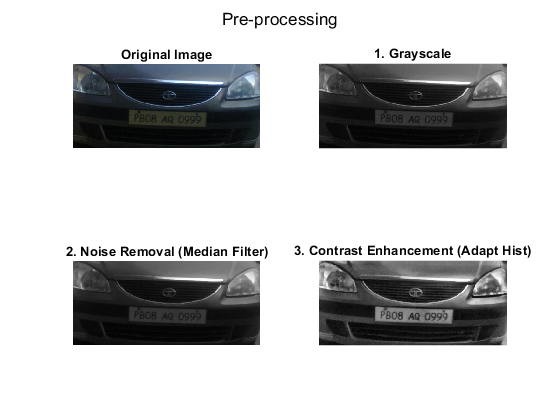

img1cont = adapthisteq(img1med);
subplot(2, 2, 4); imshow(img1cont); title("3. Contrast Enhancement (Adapt Hist)");

sgtitle("Pre-processing");

## Morphological Opening and Image Subtraction Operations

figure;

### Opening with structuring element of shape 'disk'

We open the image to remove any small objects from the foreground, while preserving the shape and size of larger objects.

se = strel('disk',15);
img1open = imopen(img1cont,se);
subplot(1, 3, 1); imshow(img1open); title("4. Disk Opening");

### Subtraction from enhanced image

In order for the binarization to work better, we subtract the opened image from the contrast enhanced one.

img1sub = imsubtract(img1cont, img1open);
subplot(1, 3, 2); imshow(img1sub); title("5. Substract from Enhanced Image");

## Image binarization

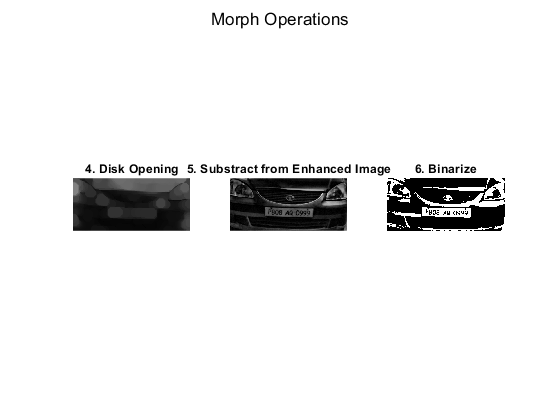

% Find grayscale threshold and binarize
bins = 19;
[counts,x] = imhist(img1sub, bins);
g_thresh = otsuthresh(counts); %graythresh(img1sub)

img1bin = imbinarize(img1sub, g_thresh);

%imshowpair(img1bin, img1bin_filled); 
subplot(1, 3, 3); imshow(img1bin); title("6. Binarize");
sgtitle("Morph Operations");

## Creating Mask

figure;

### Detect edges with the Sobel operator

img1edge = edge(img1bin);
subplot(2, 3, 1); imshow(img1edge); title("7. Sobel Edge Detection");

### Candidate plate area detection with morphological operators

#### Dilation

We dilate the image to widen the edges from the Sobel operator.

se2 = strel('square', 2);
img1dil = imdilate(img1edge, se2);
subplot(2, 3, 2); imshow(img1dil); title("8. Square Dilation");

#### Filling holes

Fill any holes in order to show plate location.

img1fill = imfill(img1dil, 'holes');
subplot(2, 3, 3); imshow(img1fill); title("9. Fill Holes");

#### Opening

Again, we open to get rid of smaller objects, gradually.

se3 = strel('square',22);
img1open = imopen(img1fill, se3);
subplot(2, 3, 4); imshow(img1open); title("10. Square Opening");

#### Remove smaller objects

img1clean = bwareaopen(img1open, 800);
subplot(2, 3, 5); imshow(img1clean); title("11. Removed small objects");

### Apply Mask

We apply the mask that resulted from the previous operation onto the previously enhanced image.

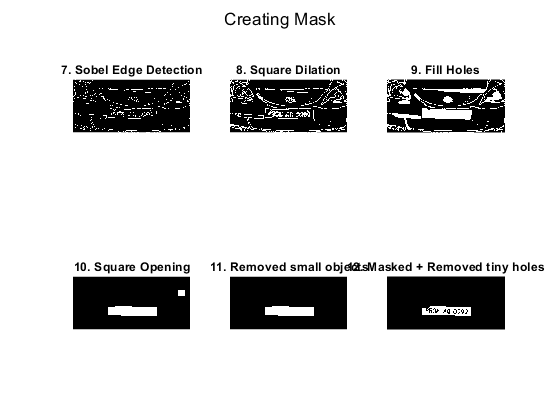

img1bin(~img1clean) = 0;

% Remove tiny holes based on size (screws at the top of plate)
img1bin_filled = ~bwareaopen(~img1bin, 20);
subplot(2, 3, 6); imshow(img1bin_filled); title("12. Masked + Removed tiny holes");

sgtitle("Creating Mask");

## OCR

With the help of OCR, we detect the characters on the license plate.

figure;

Should make it only check for 

- Letters (Language) for the first 2 letters

- Numeric for the following 2 letters

- Letters for the middle 2 letters

- Numeric digits for the last 4 digits

img_ocr = img1bin_filled;

plate_text = getLicensePlateByRegion_ocr(img_ocr, PlateTypes.Default);

Found letters:


ans = 3

  1:  PBOB
Found digits:


ans = 3

  1:  7808


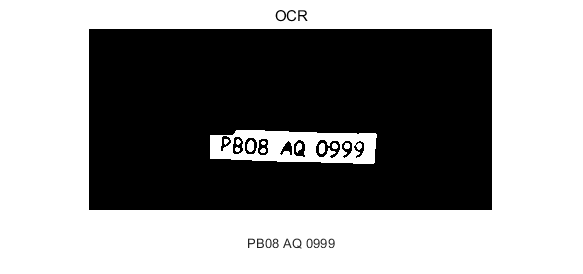

imshow(img_ocr); xlabel(plate_text);

sgtitle("OCR");

fclose('all');

## Questions

**1. What is the purpose of each step in the workflow above? **

- Steps have been explained throughout the script.

**2. State the main decisions you needed to take. For example, which filter/technique did you choose and why? **

- First off, we used Adaptive Histogram Equalization to enhance the contrast, as it seemingly gives better results than normal Histogram Equalization.

- The Sobel filter has been used for edge detection, which resulted in a satisfactory outcome.

- The series of dilation, filling, and then opening proved crucial in order to detect the location of the license plate in the picture.